# Solving the 1st Order Linear ODEs using Euler Method

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

The Euler method is a simple numerical technique used to approximate the solutions of ordinary differential equations (ODEs). It's based on the idea of approximating the derivative of a function using the tangent line at a given point. This method is especially useful when finding exact solutions to ODEs is not feasible or when solving analytically is complex.

Each 1st order ODE can be showed as a function of dependent variables. for example:


$$\frac{\textrm{dy}}{\textrm{dx}}=-2x^3 +12x^2 -20x+8\ldotp 5=f\left(x\right)$$


The iterative method is showed as follows:


$$y_{i+1} =y_i +\int_{i-1}^i y^{\prime } \;\textrm{dx}$$


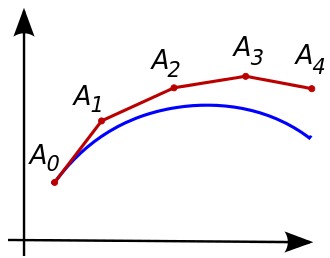

* Illustration of the Euler method. The unknown curve is in blue, and its polygonal approximation is in red.*

### Part1: Import data

clear, clc
syms x
f = input('Enter the equation of f(x,y): ');    
X = input('Enter the range of xi as a vector: ');
Y = ones(1,length(X));  % initial value of yi vector
X(1,1) = input('Enter the value of x0: ');     % Value of x0
Y(1,1) = input('Enter the value of y0: ');     % Value of y0

### Part2: ODE Calculation

for i = 2:length(X)
    Y(1,i) = int(f,X(1,i-1),X(i)) + Y(1,i-1);
end
Xi = X';
Yi = Y';
i = (0:(length(X)-1))';


### Part3: Results & Visualization

result = table(i,Xi,Yi);
disp('The results of calculation are:'), disp(result)

The results of calculation are:
    i    Xi       Yi  
    _    ___    ______

    0      0         1
    1    0.5    3.2188
    2      1         3
    3    1.5    2.2188
    4      2         2
    5    2.5    2.7188
    6      3         4



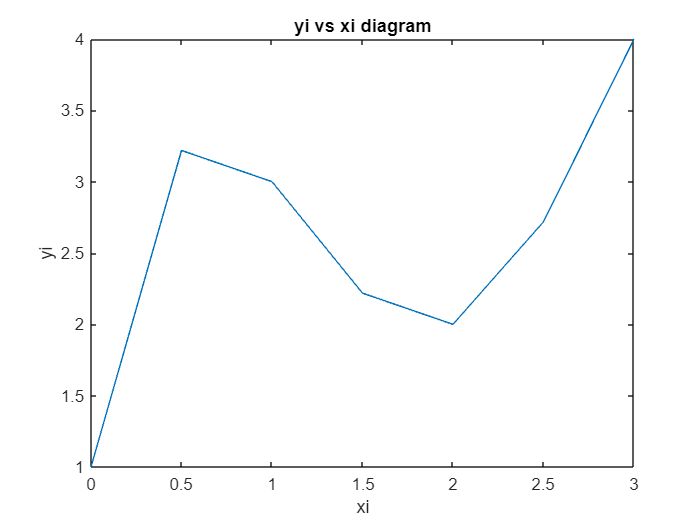

plot(X,Y)
xlabel('xi')
ylabel('yi')
title('yi vs xi diagram')